load tupleCount-DEV-MercuryErrorLog.txt
load tupleCount-MEM-MercuryErrorLog.txt
load tupleCount-I-O-MercuryErrorLog.txt
load tupleCount-NET-MercuryErrorLog.txt
load tupleCount-PRO-MercuryErrorLog.txt

Unrecognized function or variable 'dev'.

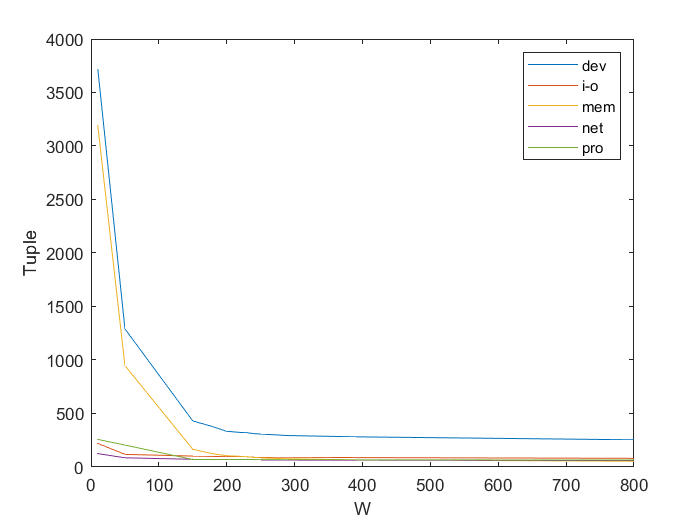

G = plot(dev(:,1), dev(:,2), io(:,1),io(:,2),mem(:,1),mem(:,2),net(:,1),net(:,2),pro(:,1), pro(:,2));
legend('dev', 'i-o', 'mem', 'net', 'pro')
xlabel('W')
ylabel('Tuple')

load tupling_DEV-MercuryErrorLog-200\interarrivals.txt

load tupling_MEM-MercuryErrorLog-200\interarrivals.txt

load tupling_I-O-MercuryErrorLog-100\interarrivals.txt

load tupling_NET-MercuryErrorLog-100\interarrivals.txt

load tupling_PRO-MercuryErrorLog-200\interarrivals.txt

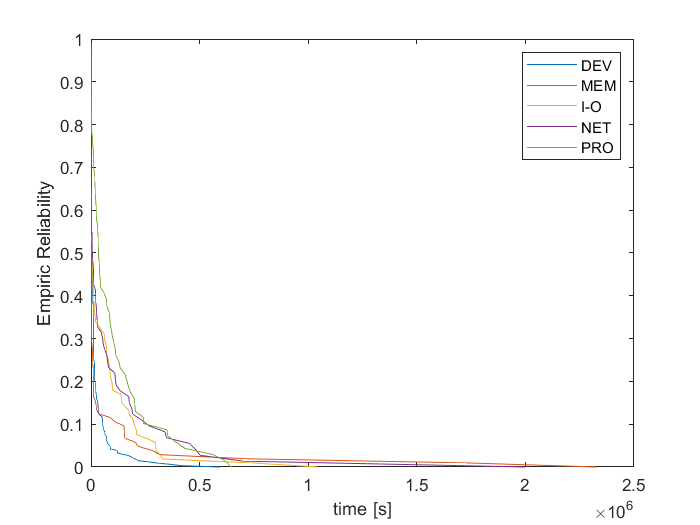


[ydev,tdev] = cdfcalc(interarrivals_dev);
[ymem,tmem] = cdfcalc(interarrivals_mem);
[yio,tio] = cdfcalc(interarrivals_io);
[ynet,tnet] = cdfcalc(interarrivals_net);
[ypro,tpro] = cdfcalc(interarrivals_pro);
empTTFdev=ydev(2:size(ydev,1));
empReldev=1-empTTFdev;

empTTFmem=ymem(2:size(ymem,1));
empRelmem=1-empTTFmem;

empTTFio=yio(2:size(yio,1));
empRelio=1-empTTFio;

empTTFnet=ynet(2:size(ynet,1));
empRelnet=1-empTTFnet;

empTTFpro=ypro(2:size(ypro,1));
empRelpro=1-empTTFpro;

plot(tdev,empReldev,tmem,empRelmem, tio,empRelio,tnet,empRelnet,tpro,empRelpro);
legend('DEV', 'MEM', 'I-O', 'NET', 'PRO')
xlabel('time [s]'); ylabel('Empiric Reliability');

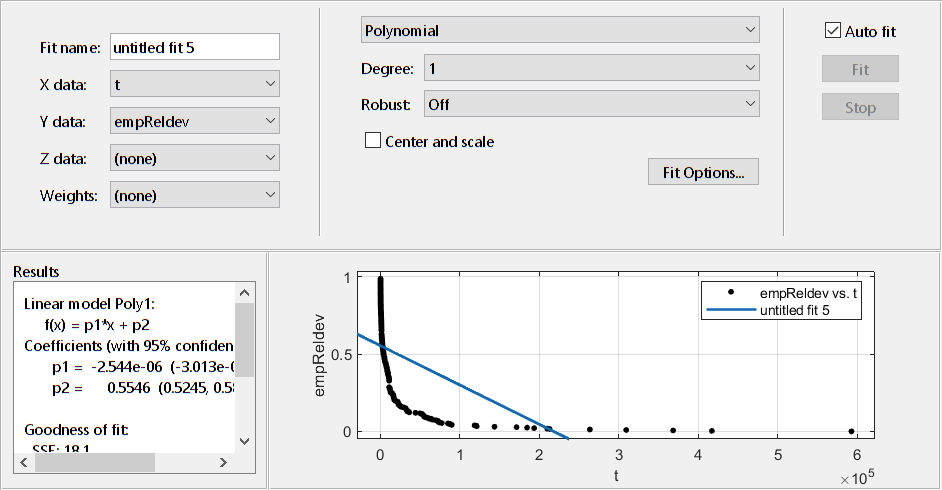

% legend('empirical TTF (DEV)', 'empirical Rel(DEV)');
cftool(t,empReldev)


%rel_dev = fit_dev.a * exp(fittedMod_Mercury.b*t) + fittedMod_Mercury.c*exp(fittedMod_Mercury.d*t);
dev = fit_dev.a * tdev .^ fit_dev.b + fit_dev.c;
mem = fit_mem.a * tmem .^ fit_mem.b +fit_mem.c;
io = fit_io.a * exp(fit_io.b * tio) + fit_io.c * exp(fit_io.d*tio);
net = fit_net.a * tnet.^fit_net.b + fit_net.c;
pro = fit_pro.a * exp(fit_pro.b * tpro) + fit_pro.c * exp(fit_pro.d*tpro);

[h,p,k] = kstest2(empReldev,dev, 'Alpha',0.05)

h = logical
   0


p = 0.3802

k = 0.0736

[h,p,k] = kstest2(empRelmem,mem, 'Alpha',0.05)

h = logical
   0


p = 0.8938

k = 0.0800

[h,p,k] = kstest2(empRelio,io, 'Alpha',0.05)

h = logical
   0


p = 0.9659

k = 0.0680

[h,p,k] = kstest2(empRelnet,net, 'Alpha',0.05)

h = logical
   0


p = 0.9998

k = 0.0548

[h,p,k] = kstest2(empRelpro,pro, 'Alpha',0.05)

h = logical
   0


p = 0.9913

k = 0.0725

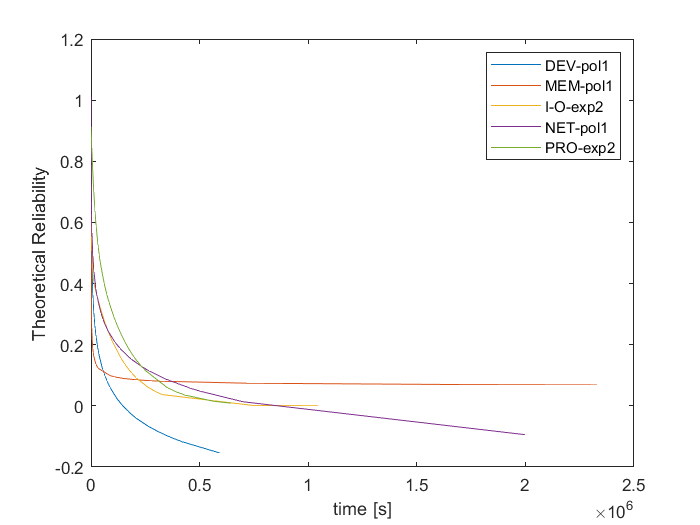


plot(tdev, dev, tmem, mem, tio, io, tnet, net, tpro, pro)
legend('DEV-pol1', 'MEM-pol1', 'I-O-exp2', 'NET-pol1', 'PRO-exp2')
xlabel('time [s]'); ylabel('Theoretical Reliability');